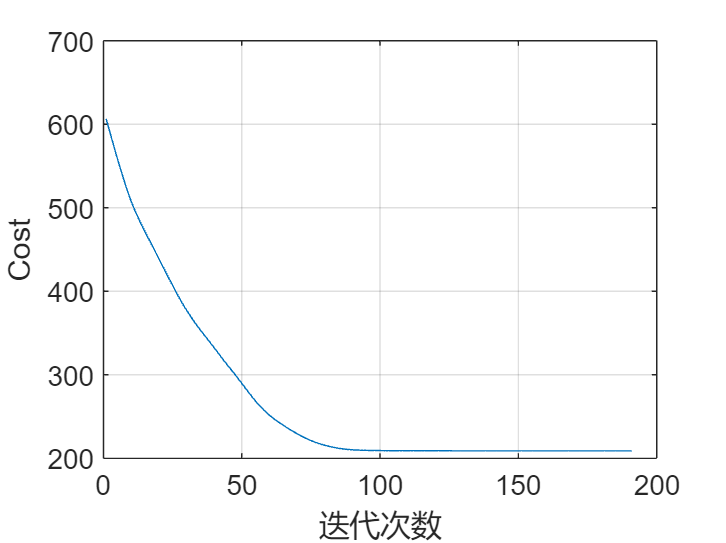

figure;
plot(Jhist);
xlabel('迭代次数');
ylabel('Cost');
grid on;

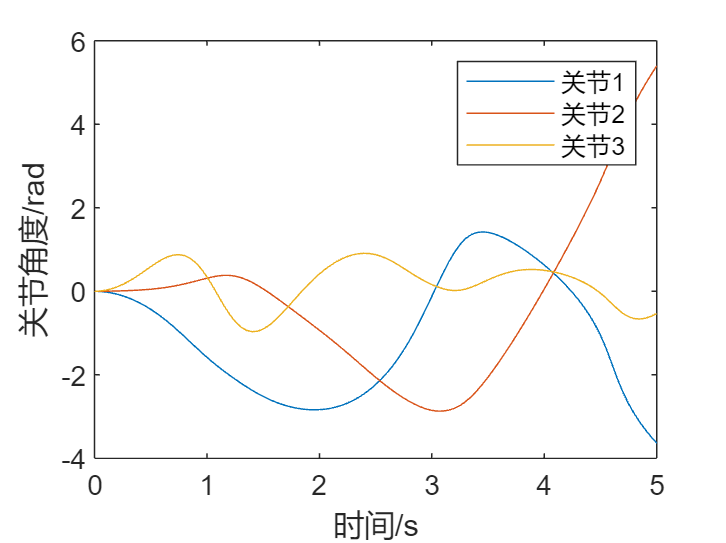

figure;
thist=0:h:Tfinal;
plot(thist,xtraj(1,:));
hold on;
plot(thist,xtraj(2,:));
hold on;
plot(thist,xtraj(3,:));
xlabel('时间/s');
ylabel('关节角度/rad');
legend('关节1','关节2','关节3');

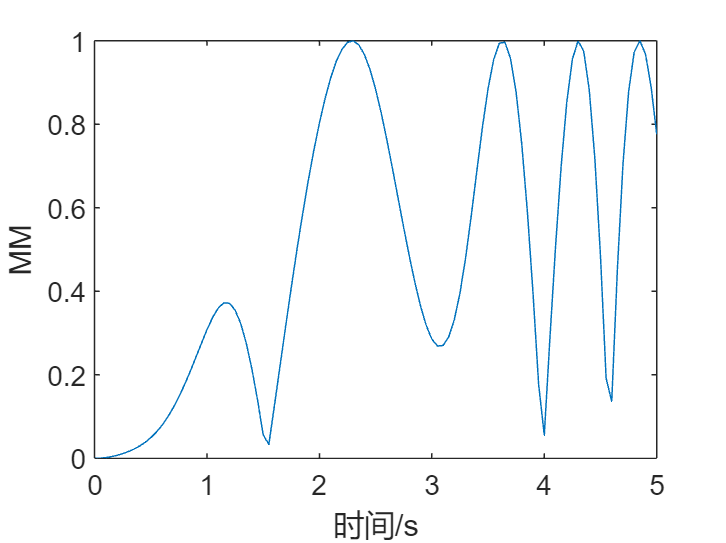

import casadi.*
for i = 1:Nu
    link = robot.links(i);
    DH(i, :) = [link.theta, link.d, link.a, link.alpha];
end  % DH矩阵
DH =MX(DH);

x =MX.sym('x',Nu,1);
Jacob = Jacob_geo(x,DH);
Jacobgeo = Function('Jacobgeo',{x},{Jacob});

for i=1:Nt
    J=full(Jacobgeo(xtraj(1:3,i)));
    J = J([1,2,6],:);
    omega(i)=sqrt(det(J*J'));
end

figure;
plot(thist,omega);
xlabel('时间/s');
ylabel('MM');